# From  fully connected neural networks to convolutional neural networks

This example shows how to perform an image classification task using both a fully connected neural network and a convolutional neural network. Moreover, the differences between the two networks are reported.

The example demonstrates how to:

- Load and explore image data.

- Define a fully connected network architecture.

- Define a convolutional neural network architecture.

- Specify training options.

- Train the network.

- Predict the labels of new data.

clear
rng(0);  % Set initial random state for example reproducibility.

## Loading and Visualizing Data

The digits data set consists of 10,000 synthetic grayscale images of handwritten digits. Each image is 28-by-28 pixels and has an associated label denoting which digit the image represents (0–9). 

The task to solve consists in classifying each image according to the handwritten digit.

The digits data is loaded as an image datastore using the [imageDatastore](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) function, that creates an `ImageDatastore` object (imds).  It acts as a reference (or a pointer)  to a data source, such as a folder of image files. When creating an imageDatastore`, `basic meta information about the data are stored, such as file names and the formats. The dataset is not imported, but images are imported when needed (e.g. during the training).

In this example, `digitDatasetPath `is the folder of image files. 

If `IncludeSubfolders` is set to true, the subfolders are included. Since each subfolder contains images of the same class, `LabelSource` is set to `foldernames`

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

Display some of the images in the datastore using [randperm](https://it.mathworks.com/help/matlab/ref/randperm.html). 

figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

## Splitting Dataset into Training, Validation and Test Sets

The data is split into three different sets:

- **Train Set**: It is used to train the networks

- **Validation Set**: It is used during the training step providing an unbiased evaluation of a model fit on the training dataset while tuning model parameters

- **Test Set**: It is the sample of data used to provide an unbiased evaluation of a final model fit on the training dataset. The test set is used after the training. 

For this example we will use 70% for training, 15% for validation and 15% for testing.

The function  [spliteachlabel](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html) splits the `imds` into three different imageDatastore objects. 

`imdsTrain` contains 70% of the images for each class, while `imdsValidation` and imdsTest include 15% of the images for each class. If `'randomized' `is specified, the function randomly assigns the specified proportion of files from each class to the new datastores.

[imdsTrain,imdsValidation, imdsTest] = splitEachLabel(imds, 0.7,0.15,0.15, 'randomized');

## Fully connected neural network definition

In this example, the classification task is performed with a fully connected neural network. 

An image can be considered as matrix of pixels of size [h,w,c], where h is the height, w is the width and  c is the number of channels. As a consequence,  it is possible to flatten the image and feed it to a fully connected neural network with fully connected layers.

The input layer is an [imageInputLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.imageinputlayer.html) and specifies the image size, which, in this case, is 28-by-28-by-1. These numbers correspond to the height, width, and the channel size. The digit data consists of grayscale images, so channel size (color channel) is 1.  Each pixel of the input image is connected with each neuron of the first [`fullyConnectedLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.fullyconnectedlayer.html) , that has 784 neurons since each image is a 28x28x1 matrix.

Each `fullyConnectedLayer`  has the rectified linear unit ([`reluLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.relulayer.html)`)` as activation function.

The size of the fully connected layers `fc_1, fc_2, fc_3` is chosen to  have a gradual reduction in the number of neurons from `fc_1` to `fc_4.`

Therefore, the `OutputSize` parameter in the last fully connected layer is equal to the number of classes in the target data. In this example, the output size is 10, corresponding to the 10 classes. 

The [`softmaxLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.softmaxlayer.html) activation function normalizes the output of the last `fullyConnectedLayer` . The output of the softmax layer consists of positive numbers that sum to one, which can then be used as classification probabilities by the classification layer.

The final layer is the [`classificationLayer`](https://it.mathworks.com/help/deeplearning/ref/classificationlayer.html). This layer uses the probabilities returned by the softmax activation function for each input to assign the input to one of the mutually exclusive classes and computes the loss. 

layers_fc  = [
    imageInputLayer([28 28 1],"Name","imageinput")
    fullyConnectedLayer(784,"Name","fc_1")
    reluLayer("Name","relu_1")
    fullyConnectedLayer(300,"Name","fc_2")
    reluLayer("Name","relu_2")
    fullyConnectedLayer(100,"Name","fc_3")
    reluLayer("Name","relu_3")
    fullyConnectedLayer(10,"Name","fc_4")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

It is possible to solve this exercise  in the** Deep Network Designer (DND), **as suggested in the Further Practice.

### Training Step 

In this section the [training options](https://it.mathworks.com/help/deeplearning/ref/trainingoptions.html) (hyperparameter) are set:

- `Max_epochs` is the number of training  epochs. An epoch is a full training cycle on the entire training data set.

- `batch_size` is the size of the batch of data used during network training. The batch size is a hyperparameter that defines the number of images to work through before updating the internal model parameters. For each training epoch, the train set is divided into batches of size 128. 

- `IterForEpoch` specifies the frequency the frequency of the validation and the frequency of verbose printing. The validation data is not used to update the network weights. 

The network is trained using `Adam` optimizer with an initial learning rate of 0.0001.

The function [trainNetwork](https://it.mathworks.com/help/deeplearning/ref/trainnetwork.html) trains the network specified by `layers_fc` for the image classification tasks using the images and labels in the image datastore `imdsTrain` and the training options defined by `options_fc`. By default, trainNetwork uses a GPU if one is available (requires Parallel Computing Toolbox™ and a CUDA® enabled GPU with compute capability 3.0 or higher). Otherwise, it uses a CPU. It is possible to specify the execution environment by using the `'ExecutionEnvironment'` name-value pair argument of `trainingOptions`.

For a classification task, the loss is the cross-entropy loss. The accuracy is the percentage of images that the network classifies correctly.

Training requires about 40 seconds to execute on GPU and 2 minutes on CPU . If `dotraining `is set to true, the trained network is then saved in 'fc_net.mat' file, using the  [save](https://it.mathworks.com/help/matlab/ref/save.html) function, otherwise a pretrained network is loaded. 

dotraining = false;

batch_size = 128;
Max_epochs = 10;
ValFreq  = floor(numel(imdsTrain.Labels) / batch_size);

options_fc = trainingOptions('adam', ...
    'Plots','training-progress',...
    "Verbose", true, ...
    "VerboseFrequency", ValFreq ,...
    "MaxEpochs", Max_epochs,...
    "MiniBatchSize", batch_size,...
    "Shuffle","every-epoch",...
    "ValidationData", imdsValidation, ...
    "ValidationFrequency",ValFreq ,...
    "InitialLearnRate", 0.0001,...
    "LearnRateSchedule","none", ...
    "L2Regularization", 0.0001,...
    "ExecutionEnvironment","auto");

if dotraining
    net_fc = trainNetwork(imdsTrain, layers_fc, options_fc);
    save('fc_net.mat', 'net_fc');
else
    net_fc = load('fc_net.mat');
    net_fc = net_fc.net_fc;
end

Note, your validation accuracy should be approximately 80%

## Convolutional Neural Network definition

In this example, the classification task is also performed with a convolutional neural network.

In the convolutional layer ([convolution2dLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.convolution2dlayer.html)), the first argument is `filterSize`, which is the height and width of the filters the training function uses while scanning along the images. In this example, the number 3 indicates that the filter size is 3-by-3. The second argument is the number of filters, `numFilters`, which is the number of neurons that connect to the same region of the input. This parameter determines the number of feature maps.  For a convolutional layer with a default stride of 1, `'same'` padding ensures that the spatial output size is the same as the input size. 

Batch normalization layers ([batchNormalizationLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.batchnormalizationlayer.html)) normalize the activations and gradients propagating through a network, making network training an easier optimization problem.  The batch normalization layer is followed by a nonlinear activation function. The most common activation function is the rectified linear unit ReLU.

Convolutional layers (with activation functions) are often followed by a down-sampling operation that reduces the spatial size of the feature map and removes redundant spatial information. Down-sampling makes it possible to increase the number of filters in deeper convolutional layers without increasing the required amount of computation per layer. The  [`maxPooling2dLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.maxpooling2dlayer.html) layer returns the maximum values of rectangular regions of inputs, specified by the first argument, `poolSize`. In this example, the size of the rectangular region is [2,2]. The `'Stride'` name-value pair argument specifies the step size that the training function takes as it scans along the input.

The convolutional and down-sampling layers are followed by one or more fully connected layers.The output size of the last fully connected layer is equal to the number of classes in the target data.

The output of the softmax layer is used as classification probabilities by the classification layer.

The hyperparameters used here were found by trial-and-error and can differ if a different data set is used

layers_cnn = [
    imageInputLayer([28 28 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

### Training step

In this section the training options (hyperparameter) are set. 

After defining the network structure, the training options are specified. The network is trained using Adam optimizer with an initial learning rate of 0.0001 for a maximum number of epochs equal to 30.  The network accuracy during training is monitored by specifying validation data and validation frequency. 

Training requires about 5 minutes  to execute on GPU. If `dotraining` is set to true, the trained network is then saved in 'cnn_net.mat' file, using the save function, otherwise a pretrained network is loaded. 

dotraining = false;

batch_size = 128;
Max_epochs = 30;
ValFreq  = floor(numel(imdsTrain.Labels) / batch_size);

option_cnn = trainingOptions('adam', ...
    'Plots','training-progress',...
    "Verbose", true, ...
    "VerboseFrequency", ValFreq ,...
    "MaxEpochs", Max_epochs,...
    "MiniBatchSize", batch_size,...
    "Shuffle","every-epoch",...
    "ValidationData", imdsValidation, ...
    "ValidationFrequency",ValFreq ,...
    "InitialLearnRate", 0.0001,...
    "LearnRateSchedule","none", ...
    "L2Regularization", 0.0001,...
    "ExecutionEnvironment","auto");

if dotraining
    net_cnn = trainNetwork(imdsTrain, layers_cnn, option_cnn);
    save('cnn_net.mat', 'net_cnn');
else 
    net_cnn = load('cnn_net.mat');
    net_cnn = net_cnn.net_cnn;
end 

The training progress should look similar to this:

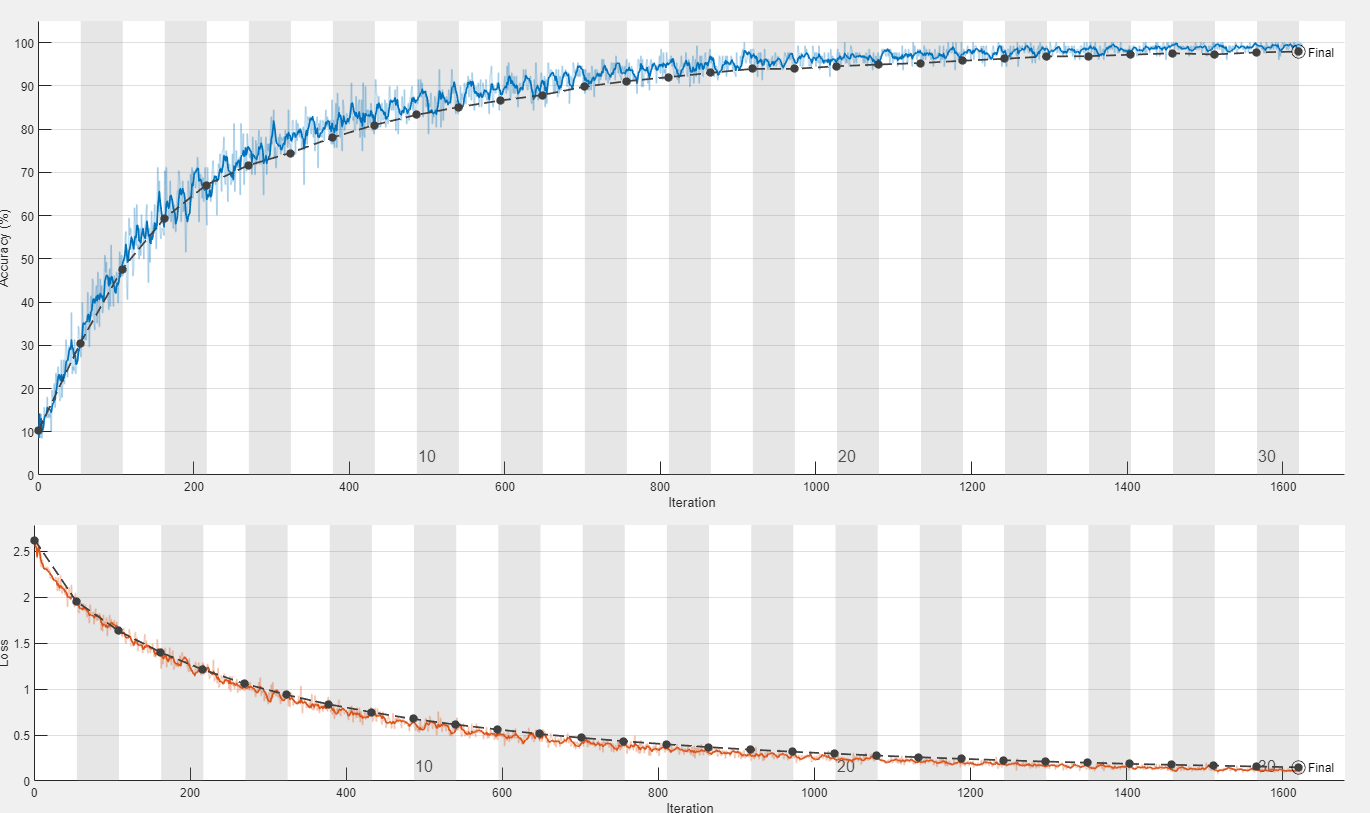

Note, your validation accuracy should be approximately 97%

## Performance Evaluation

In this section predictions on the test set (imdsTest) are computed.

The performance of  both the fully connected neural network and the convolutional neural network are evaluated. 

Predictions on the test set are computed using [classify](https://it.mathworks.com/help/deeplearning/ref/seriesnetwork.classify.html) function. To compare the trained models, the same test set is used. 

The function [confusionchart](https://it.mathworks.com/help/stats/confusionchart.html) creates the confusion matrix chart for the classification problem.

pred_fc = classify(net_fc, imdsTest);
acc_fc = sum(imdsTest.Labels == pred_fc)/numel(imdsTest.Labels);
disp(['Accuracy ANN ' num2str(acc_fc*100) '%'])
figure
cm_fc = confusionchart(imdsTest.Labels,pred_fc);
title('Performance with ANN');

pred_cnn = classify(net_cnn, imdsTest);
acc_cnn = sum(imdsTest.Labels == pred_cnn)/numel(imdsTest.Labels);
disp(['Accuracy CNN ' num2str(acc_cnn*100) '%'])
figure;
cm_cnn = confusionchart(imdsTest.Labels,pred_cnn);
title('Performance with CNN');

The convolutional neural network outperforms the fully connected neural network in terms of accuracy for each class. 

## Further Practice

- Try to change the architecture of both fully connected neural network and convolutional neural network. Use Deep Network Designer App (DND) that provides a graphical interface for designing a neural network.

To open the DND app go to the **Apps** tab, under **Machine Learning and Deep Learning**, click the  icon. Alternatively, you can open the app from the command line [`deepNetworkDesigner`](https://uk.mathworks.com/help/deeplearning/ug/build-networks-with-deep-network-designer.html).

## Further readings

- [imageDatastore](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html)

-  [spliteachlabel](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html)

- [imageInputLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.imageinputlayer.html)

- [`fullyConnectedLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.fullyconnectedlayer.html)

- [`reluLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.relulayer.html)

- [`softmaxLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.softmaxlayer.html)

- [`classificationLayer`](https://it.mathworks.com/help/deeplearning/ref/classificationlayer.html)

- [convolution2dLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.convolution2dlayer.html)

- [batchNormalizationLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.batchnormalizationlayer.html)

-  [`maxPooling2dLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.maxpooling2dlayer.html)

-  [save](https://it.mathworks.com/help/matlab/ref/save.html)

- [load](https://it.mathworks.com/help/matlab/ref/load.html)

- [confusionchart](https://it.mathworks.com/help/stats/confusionchart.html)